# **5 Natural dynamics of ID (Measles)**

 Set up the SEIR model with births and deaths for the transmission dynamics of measles in a closed population using differential equations:

- Population 100000 people

- Pre-infectious period 8 days

- Infectious period 7 days

- Basic reproduction number 13

- Life Expectancy 70 years

- Initial values (S,E,I,R)=(99999,0,1,0)

Using the parameters above, plot a graph from the 40th year to the 50th year which illustrates your answer for each question.

clear; close all; clc;

N = 100000;
preinf = 8;
D = 7;
r0 = 13;
life = 70;

beta = r0/(N*D);
f = 1/preinf ;
r = 1/D ;
d = 1/(life*365);
b = d;
herd = 1-1/r0;

% Initial values
S0 = 99999;
E0 = 0;
I0 = N - S0;
R0 = 0;

% Time
dt = 1;
t_start = 0;
t_end = 365*150;
tspan = t_start:dt:t_end;

▶Using Differential equation

fode = @(t,y) [-beta*y(1)*y(3) + b*N - d*y(1);
                beta*y(1)*y(3) - f*y(2) - d*y(2);
                f*y(2) - r*y(3) - d*y(3);
                r*y(3) - d*y(4) ] ;

            
[~,sol] = ode45 (fode, tspan, [S0; E0; I0; R0]); 

S = sol(:,1);   
E = sol(:,2);   
I = sol(:,3);   
R = sol(:,4);   

propsus = sol(:,1) / N;   % S/N
propimm = sol(:,4) / N;   % R/N
Rn = r0 * propsus;        % Rn = R0 * S/N

new_preinf = beta * (S(1:end-1) .* I(1:end-1) + S(2:end) .* I(2:end)) / 2;
new_inf = f * (E(1:end-1) + E(2:end)) / 2;
Epidemic_threshold = ones(length(tspan),1)./r0;
h = ones(length(tspan),1).*herd;

#### 1.How does the net reproduction number change over time? What is the value of the net reproduction number when the daily number of new infectious peaks? What is its value when the daily number of new infectious persons reaches a trough?

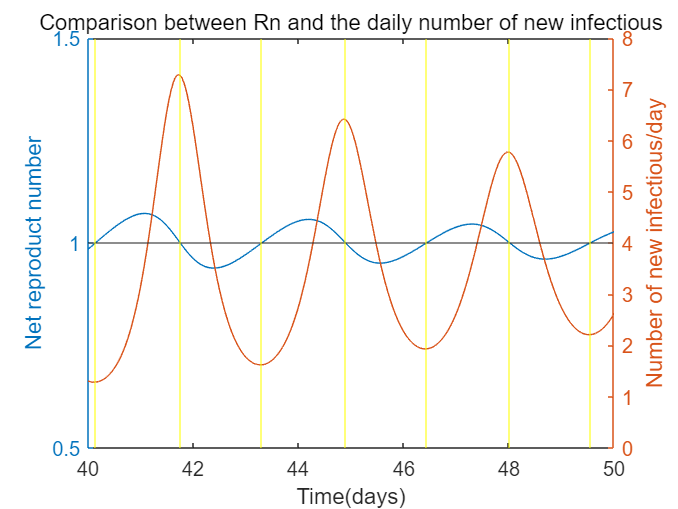

forward = Rn(1:end-1)-1;
back = Rn(2:end)-1;
ind=forward.*back;
index = find(ind<0);

figure(1)
yyaxis left % y축 왼쪽 
plot (tspan./365,Rn);
yline(1);
for i = 1:length(index)
    xline(index(i)./365,'-y');
end
xlim ([40, 50]);
xlabel ('Time(years)');
ylabel ('Net reproduct number')
ylim ([0.5,1.5]);
hold on;

yyaxis right % y축 오른쪽
plot (tspan(2:end)./365,new_preinf);
xlim ([40, 50]);
xlabel ('Time(days)');
ylabel ('Number of new infectious/day');
ylim ([0,8]);
hold on ;


title ('Comparison between Rn and the daily number of new infectious');

#### 2. What is the trend in the daily number of new infectious when Rn<1, Rn>1, and Rn=1, respectively? 

Rn<1 일때 the daily number of new infectious가 증가하다가, R_n=1일때 peak를 찍고 ,Rn<1이면 다시 new infec이 감소하는 과정을 반복한다.

#### 3. What proportion of the population is susceptible to infection when the daily number of new infectious peaks or troughs? Is this consistent with what you expect and why?

When the daily number of new infectious peaks, I think that the proportion of Susceptible is 1/$R_0$ (=0.0769). This is consistent with what I expect.

#### 4. Calculate the herd immunity threshold in this population.

fprintf('When Rn = 1 the daily number of susceptible = %f \n',1/r0);

When Rn = 1 the daily number of susceptible = 0.076923 


fprintf('Herd immunity threshold = %f',herd);

Herd immunity threshold = 0.923077

#### 5. What is the value of proportion of immune when the number of new infectious per day peaks or troughs? What do you notice about the value of proportion of immune when the daily number of new infectious is declining? What is its value when the daily number of new infectious is increasing? How does this relate to your estimate of the herd immunity threshold?

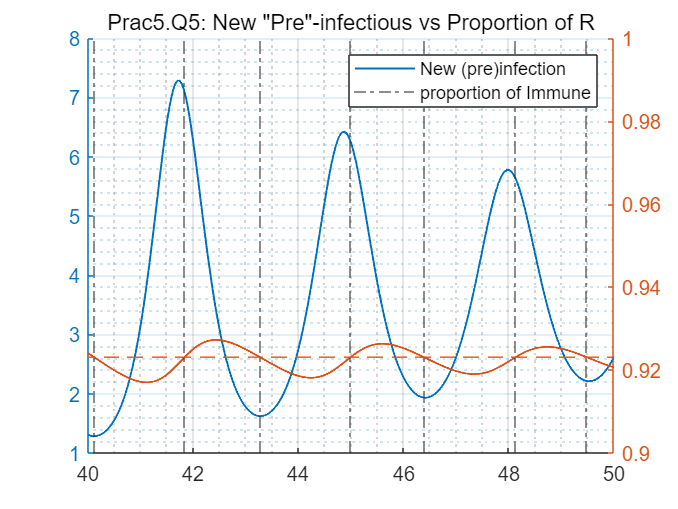

forward = propimm(1:end-1)-herd;
back = propimm(2:end)-herd;
ind=forward.*back;
index = find(ind<0);

figure(2)
hold on;
yyaxis left
plot(tspan(2:end)./365,new_preinf,'-','linewidth',1)
for i = 1:length(index)
    xline(index(i)./365,'-.');
end
yyaxis right
plot(tspan./365,propimm,'-','linewidth',1)
ylim([0.9,1])
plot(tspan./365,h,'--')
legend('New (pre)infection','proportion of Immune')
grid on; grid minor;
xlim([40,50])
title('Prac5.Q5: New "Pre"-infectious vs Proportion of R')
hold off

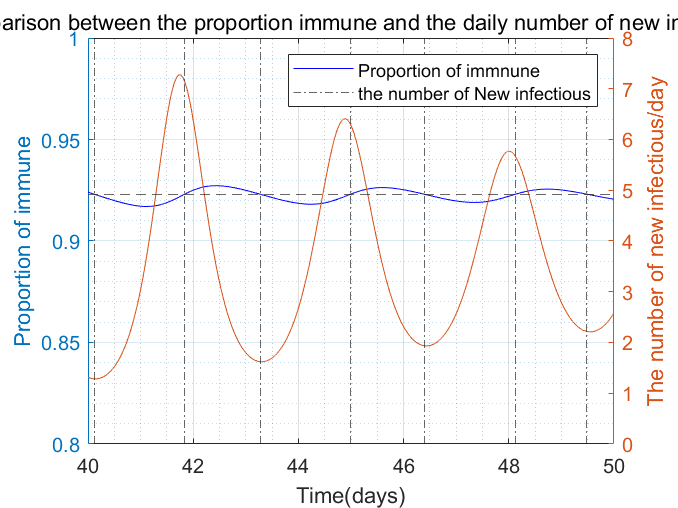

figure(3)
yyaxis left % y축 왼쪽 
plot (tspan./365,propimm,'-b');
for i = 1:length(index)
    xline(index(i)./365,'-.');
end
yline(herd,'--')
xlim ([40, 50]);
xlabel ('Time(days)');
ylabel ('Proportion of immune')
ylim ([0.8,1.0]);
hold on;

yyaxis right % y축 오른쪽
plot (tspan(2:end)./365,new_inf);
xlim ([40, 50]);
xlabel ('Time(days)');
ylabel ('The number of new infectious/day')
ylim ([0,8]);
hold on ;

title ('Comparison between the proportion immune and the daily number of new infectious');
legend ('Proportion of immnune', 'the number of New infectious');

grid on; grid minor;

#### 6. What is the long-term equilibrium value for the proportion of the population which is susceptible or immune? How do these values relate to the herd immunity threshold which you have just calculated and why?

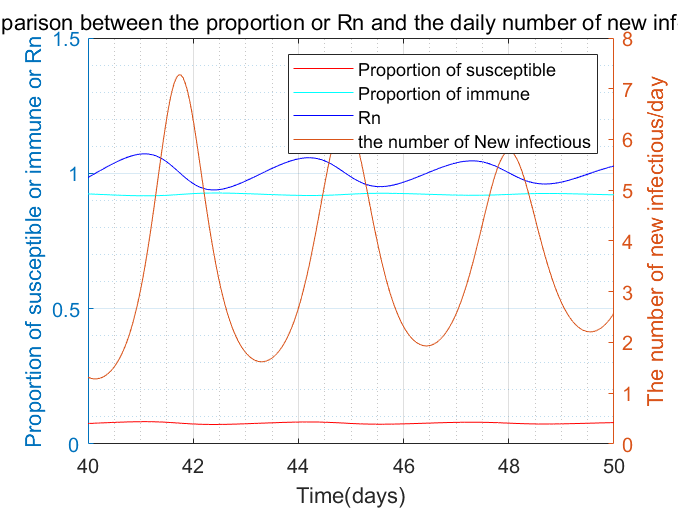

figure(4)
yyaxis left % y축 왼쪽
hold on
plot (tspan./365,propsus, '-r');
plot (tspan./365,propimm, '-c');
plot (tspan./365,Rn, '-b');
xlim ([40, 50]);
xlabel ('Time(days)');
ylabel ('Proportion of susceptible or immune or Rn')
ylim ([0,1.5]);
hold off;


yyaxis right % y축 오른쪽
plot (tspan(2:end)./365,new_inf);
xlim ([40, 50]);
xlabel ('Time(days)');
ylabel ('The number of new infectious/day')
ylim ([0,8]);

title ('Comparison between the proportion or Rn and the daily number of new infectious');
legend ('Proportion of susceptible', 'Proportion of immune', 'Rn', 'the number of New infectious');

grid on; grid minor;

## **PART 2 : Vaccination**

Modify the model to include the vaccination which is introduced 50 years after the infection has been circulating in the population so that a proportion of newborn individuals are effectively vaccinated. Run the model for 80 years and plot the proportion of immune and the number of new infectious on each side of y-axis.

%% Parameter
clear; clc;

N = 100000;
preinf = 8;% days
D = 7;% days
r0 = 13;
life = 70; %years

% parameter set
beta = r0/(N*D);
f = 1/preinf ;
r = 1/D ;
d = 1/(life*365);
b = d;
h = 1-1/r0;

% Initial values
S0 = 99999;
E0 = 0;
I0 = N - S0;
R0 = 0;

dt = 1;% 1 day
t_start = 0;
t_end = 365*150;
tspan = t_start:dt:t_end;
nt = length(tspan);

%% ODE 2 insert vac60
vacc_val = [0 60 90 93];
cov_type = length(vacc_val);
S = zeros(length(tspan), cov_type);
E = zeros(length(tspan), cov_type);
I = zeros(length(tspan), cov_type);
R = zeros(length(tspan), cov_type);
propsus = zeros(size(S));
propimm = zeros(size(S));
Rn = zeros(size(S));
new_preinf = zeros(length(tspan)-1, length(vacc_val));
new_inf = zeros(size(new_preinf));
new_recov = zeros(size(new_preinf));

%ODE
for i = 1:cov_type
fode = @(t,y) [-beta*y(1)*y(3) + (1-prac5_vac(vacc_val(i),t))*b*N - d*y(1);
                beta*y(1)*y(3) - f*y(2) - d*y(2);
                f*y(2) - r*y(3) - d*y(3);
                r*y(3) + prac5_vac(vacc_val(i),t)*b*N - d*y(4) ] ;
            
[~,sol] = ode45 (fode, tspan, [S0; E0; I0; R0]); 

S(:,i) = sol(:,1);
E(:,i) = sol(:,2);
I(:,i) = sol(:,3);
R(:,i) = sol(:,4);

propsus(:,i) = S(:,i) / N;
propimm(:,i) = R(:,i) / N;
Rn(:,i) = r0 * propsus(:,i);
end

%% Get new incidence
for i = 1:cov_type
new_preinf(:,i) = beta * (S(1:end-1,i) .* I(1:end-1,i) + S(2:end,i) .* I(2:end,i)) / 2;
new_inf(:,i) = f * (E(1:end-1,i) + E(2:end,i)) / 2;
new_recov(:,i) = r * (I(1:end-1,i) + I(2:end,i)) / 2;
end

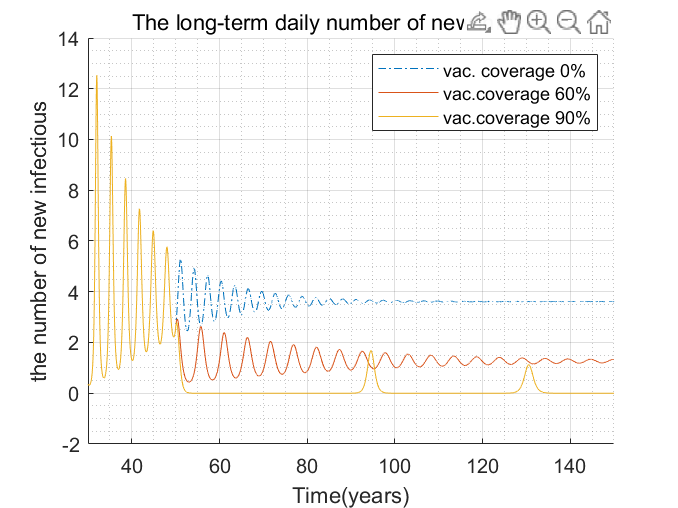

figure(5)
hold on;
plot (tspan(2:end)/365,new_inf(:,1),'-.');
plot (tspan(2:end)/365,new_inf(:,2));
plot (tspan(2:end)/365,new_inf(:,3));
xlim ([30, 150]);
xlabel ('Time(years)');
ylabel ('the number of new infectious')
title ('The long-term daily number of new infectious')
legend ('vac. coverage 0%', 'vac.coverage 60%', 'vac.coverage 90%')

grid on; grid minor;

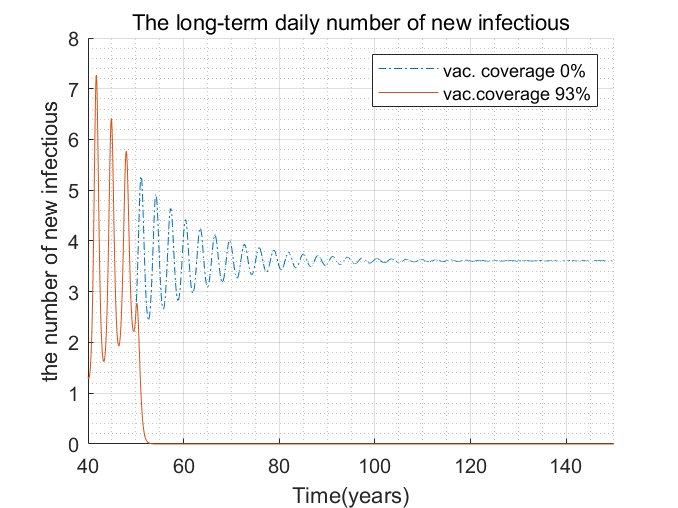

figure(6)
hold on;
plot (tspan(2:end)./365,new_inf(:,1),'-.');
plot (tspan(2:end)./365,new_inf(:,4));
xlim ([40, 150]);
xlabel ('Time(years)');
ylabel ('the number of new infectious')
title ('The long-term daily number of new infectious')
legend ('vac. coverage 0%', 'vac.coverage 93%')

grid on; grid minor;

function y = prac5_vac(cov,t)
    if t > 50*365
        y = cov./100;
        else 
        y = 0;
    end
end

To explore how R0 and other factors (e.g. the vaccination coverage, the birth rate in the population) affect the inter-epidemic period, reset the proportion of the population which is vaccinated to be zero.

#### 8. What is the inter-epidemic period 50-100 years after the introduction of one infectious case into this population? Are your results consistent with the following formula provided by Anderson and May?

####                                             
$$T=2\pi \;\sqrt{\frac{L\left(D+D^{\prime } \right)}{R_0 -1}\;}$$


#### where D’ is the average duration of the pre-infectious period, D is the average duration of infectiousness, L is the life expectancy.

#### 9. R0 for measles was estimated to be about 5-6 in Kansas 1918-9, and 18 in England and Wales in 1950-68. Run the model for values of R0 of 5 and 18. How does the inter-epidemic period resulting from an R0 of 18 compare against that resulting from an R0of 5? Why might this occur?

#### 10. How might you expect the introduction of vaccination to affect the inter-epidemic period?

#### 11. How might the birth rate in the population influence the inter-epidemic period? Test your hypothesis by changing the birth rate assuming that the population size remains constant over time.

#### 12. Would you expect the inter-epidemic period for measles to be shorter than that for chickenpox? mumps? rubella? Why?

#### 13. Change the parameters to be those for influenza (pre-infectious and infectious periods of

#### 14. 2 days and a basic reproduction number of 2), reset the birth rate corresponding to a life expectancy of 70 years and, making sure that no-one is vaccinated in the population. Why might you be cautious about using predictions of the inter-epidemic period for influenza from this model?